# ACTIVITY M4-01: GRAPHING IN COMPUTATIONAL ENVIRONMENTS

Carlos Armando Colmenares Acosta - A01663510

## Exercise one

clear;
clc;
close all;

F = (y^2, -x^2)

C: y = 4x^2    (0,0) ---> (1,4)

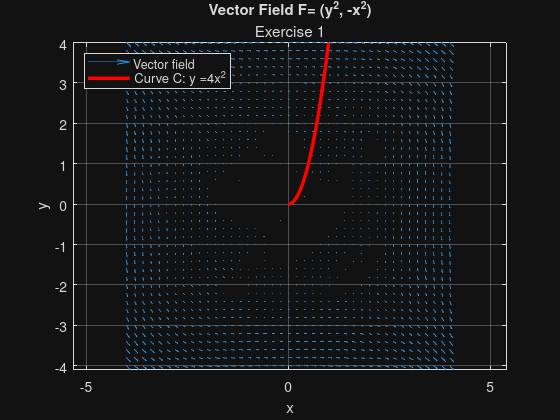

%Define de grid of points (x,y)
[x,y] = meshgrid(-4:0.2:4);

%u is f_x, v is f_y from y
u = y.^2;
v = -x.^2;

% use command quiver
quiver(x,y,u,v,0.5);
hold on;

%add the parametrized curve C
t_vals = linspace(0,1,100);
x_curve = t_vals;
y_curve = 4 * t_vals.^2;
plot(x_curve,y_curve,'r-', 'LineWidth',2.5);

%add direction arrows along the curve
t_arrows = 0.2:0.2:0.8; %4 tiny arrows along the curve

for t = t_arrows
    %point on the curve
    xa = t;
    ya = 4 * t.^2;

    %tangent vector
    dx = 0.05;
    dy = 8*t*dx;

    %use quiver to draw the arrows along c
    quiver(xa,ya,dx,dy,0,'r','LineWidth',2,'MaxHeadSize',2);

end

%plot settings
xlabel("x");
ylabel("y");
title("Vector Field F= (y^2, -x^2)");
subtitle("Exercise 1");
legend({'Vector field', 'Curve C: y =4x^2'}, 'Location', 'northwest');

%axes scales equal
axis equal;
%xlim([-2,2]);
%ylim ([-2,2]);
grid on;
hold off

## Exercise two

clear;
clc;
close all;

F = (y^2, -x^2)

C: Straight from (0,0) ---> (1,4)

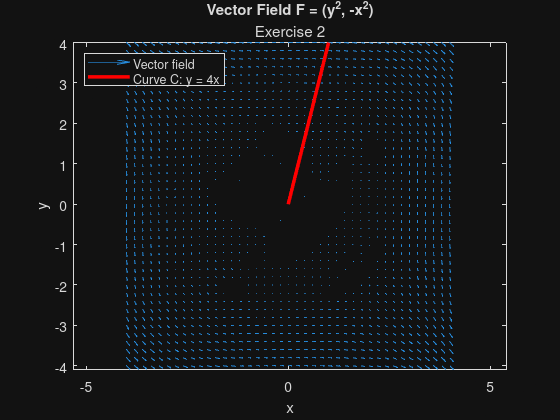

%Define de grid of points (x,y)
[x,y] = meshgrid(-4:0.2:4);

%u is f_x, v is f_y from y
u = y.^2;
v = -x.^2;

% use command quiver
quiver(x,y,u,v,0.5);
hold on;

%add the parametrized curve C
t_vals = linspace(0,1,100);
x_curve = t_vals;
y_curve = 4 * t_vals;
plot(x_curve,y_curve,'r-', 'LineWidth',2.5);

%add direction arrows along the curve
t_arrows = 0.2:0.2:0.8; %4 tiny arrows along the curve

for t = t_arrows
    %point on the curve
    xa = t;
    ya = 4 * t;

    %tangent vector
    dx = 0.05;
    dy = 4*dx;

    %use quiver to draw the arrows along c
    quiver(xa,ya,dx,dy,0,'r','LineWidth',2,'MaxHeadSize',2);

end

%plot settings
xlabel("x");
ylabel("y");
title("Vector Field F = (y^2, -x^2)");
subtitle("Exercise 2");
legend({'Vector field', 'Curve C: y = 4x'}, 'Location', 'northwest');

%axes scales equal
axis equal;

%xlim([-2,2]);

#### Comparison for exercises one and two

Despite not having calculated the work itself for this exercise as it was only asked to plot, the work done by the vector field F=[y^2,−x^2] depends on the path taken (a curve or a straight line). 

Although both trajectories start at (0,0) and end at (1,4), curved line will require less work done in comparisson to the straight line. We can conclude that the given vector field is a non-conservative one.

## Exercise 3

clear; close all; clc;

F = (xy, x^2 * y^2 )

C: Straight from (2,0) ---> (0,2)

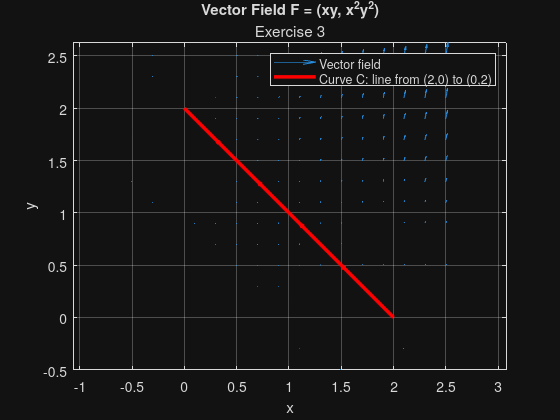

% Define the grid of points (x,y)
[x,y] = meshgrid(-0.5:0.2:2.5);

% u is F_x, v is F_y
u = x .* y;
v = (x.^2) .* (y.^2);

% use command quiver
quiver(x, y, u, v, 0.5);
hold on;

% add the parametrized curve C
t_vals = linspace(0, 1, 100);
x_curve = 2 - 2*t_vals;
y_curve = 2*t_vals;
plot(x_curve, y_curve, 'r-', 'LineWidth', 2.5);

%direction arrows along the curve
t_arrows = 0.2:0.2:0.8; %arrows along the curve

for t = t_arrows
    % point on the curve
    xa = 2 - 2*t;
    ya = 2*t;

    % tangent vector
    dx = -2 * 0.05;
    dy = 2 * 0.05;

    % use quiver to draw the arrows along c
    quiver(xa, ya, dx, dy, 0, 'r', 'LineWidth', 2, 'MaxHeadSize', 2);
end

%plot settings
xlabel("x");
ylabel("y");
title("Vector Field F = (xy, x^2y^2)");
subtitle("Exercise 3");
legend({'Vector field', 'Curve C: line from (2,0) to (0,2)'}, 'Location', 'northeast');
axis equal;
grid on;
hold off

## Exercise 4

clear; close all; clc;

F = (xy, x^2 * y^2 )

C: quarter circle from (2,0) to (0,2)

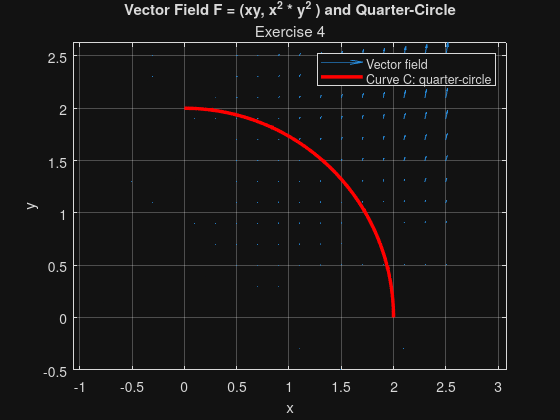

% Define the grid of points (x,y)
[x,y] = meshgrid(-0.5:0.2:2.5);

% u is F_x, v is F_y
u = x .* y;
v = (x.^2) .* (y.^2);

% use  quiver
quiver(x, y, u, v, 0.5);
hold on;

%parametrized curve C (quarter-circle on x,x)
t_vals = linspace(0, pi/2, 100);
x_curve = 2 * cos(t_vals);
y_curve = 2 * sin(t_vals);
plot(x_curve, y_curve, 'r-', 'LineWidth', 2.5);

%direction arrows along the curve
% pi/2 is approx 1.57, so arrows are placed between 0.2 and 1.4
t_arrows = 0.2:0.3:1.4; 

for t = t_arrows
    % point on the curve
    xa = 2 * cos(t);
    ya = 2 * sin(t);

    % tangent vector (derivatives)
    dx = -2 * sin(t) * 0.05;
    dy = 2 * cos(t) * 0.05;

    %use quiver to draw the arrows along c
    quiver(xa, ya, dx, dy, 0, 'r', 'LineWidth', 2, 'MaxHeadSize', 2);
end

% plot settings
xlabel("x");
ylabel("y");
title("Vector Field F = (xy, x^2 * y^2 ) and Quarter-Circle");
subtitle("Exercise 4");
legend({'Vector field', 'Curve C: quarter-circle'}, 'Location', 'northeast');
axis equal;
grid on;
hold off

## Exercise 5

clear; close all; clc;

Parametrized helix

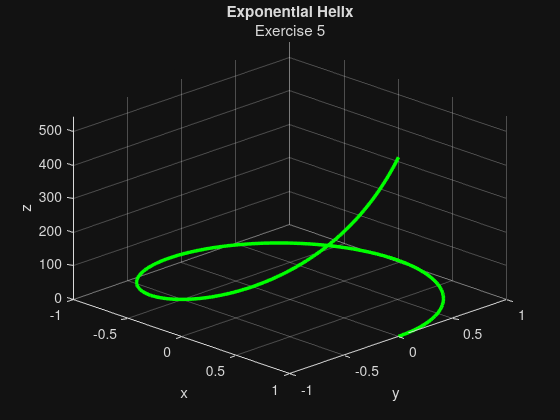

%parametrized helix
t = linspace(0,2*pi,500);
x = cos(t);
y = sin(t);
z = exp(t);

%plot the curve
figure;
plot3(x, y, z, 'g-','LineWidth', 2.5);
hold on;

%plot settings
xlabel('x');
ylabel('y');
zlabel('z');
title('Exponential Helix');
subtitle("Exercise 5");
grid on;
%axis equal; %the z scale is just too big
view(45,30); %starting 3D angle
zlim([0, exp(2*pi)+10]);
hold off

## Electric field of a positive point charge

clear; close all; clc;

Positive point charge

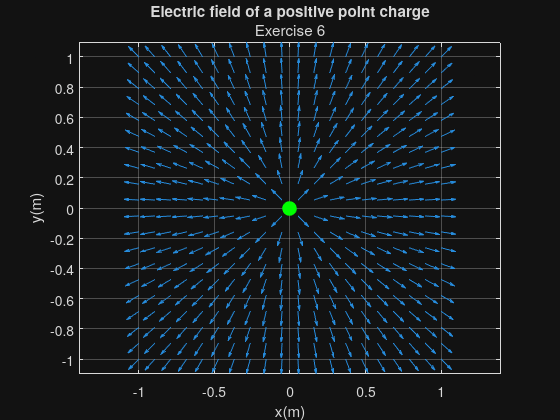

%constants
k = 9e9;
q = 1e-9;

%define the grid
x = linspace(-1,1,20);
y = linspace(-1,1,20);
[X,Y] = meshgrid(x,y);

%define the distance from q
R = sqrt(X.^2 + Y.^2);
%avoid the origin (div by 0)
R ( R==0 ) = eps;

%define electric field, E_x, E_y
E_mag = k * q ./ R.^2;
Ex = E_mag .* (X./R);
Ey = E_mag .* (Y./R);

%normalize vectors
Ex_Norm = Ex ./ sqrt(Ex.^2 + Ey.^2);
Ey_Norm = Ey ./ sqrt(Ex.^2 + Ey.^2);

%plotting
figure;
quiver(X,Y,Ex_Norm, Ey_Norm, 0.7);
hold on;

%draw the point charge in green
plot(0,0,'go','MarkerSize', 10, 'MarkerFaceColor','g');

%formatting
axis equal;
xlabel("x(m)");
ylabel("y(m)");
title("Electric field of a positive point charge");
subtitle("Exercise 6");
grid on;
hold off

## Electric field of a negative point charge

clear; close all; clc;

Negative point charge

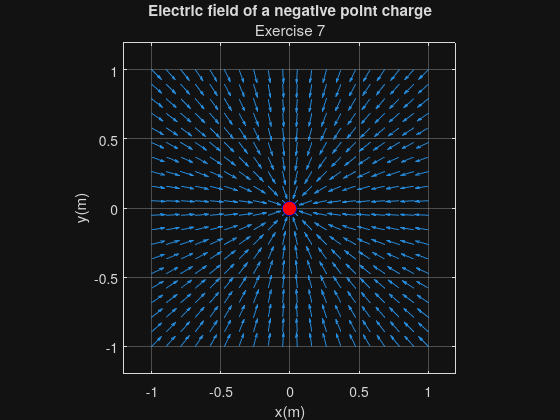

%constants
k = 9e9;
q = -1e-9; %Negative charge

%define the grid
x = linspace(-1,1,20);
y = linspace(-1,1,20);
[X,Y] = meshgrid(x,y);

%define the distance from q
R = sqrt(X.^2 + Y.^2);
%avoid the origin (div by 0)
R(R==0) = eps;

%define electric field, E_x, E_y
%q is negative, E_mag will be negative, flipping the vector directions
E_mag = k * q ./ R.^2;
Ex = E_mag .* (X./R);
Ey = E_mag .* (Y./R);

%normalize vectors
Ex_Norm = Ex ./ sqrt(Ex.^2 + Ey.^2);
Ey_Norm = Ey ./ sqrt(Ex.^2 + Ey.^2);

%plotting
figure;
quiver(X, Y, Ex_Norm, Ey_Norm, 0.7);
hold on;

%draw the negative point charge in red
plot(0, 0, 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'r');

%formatting
axis equal;
xlim([-1.2, 1.2]); 
ylim([-1.2, 1.2]);
xlabel("x(m)");
ylabel("y(m)");
title("Electric field of a negative point charge");
subtitle("Exercise 7");
grid on;
hold off;

## Electric field of a dipole

clear; close all; clc;

Dipole

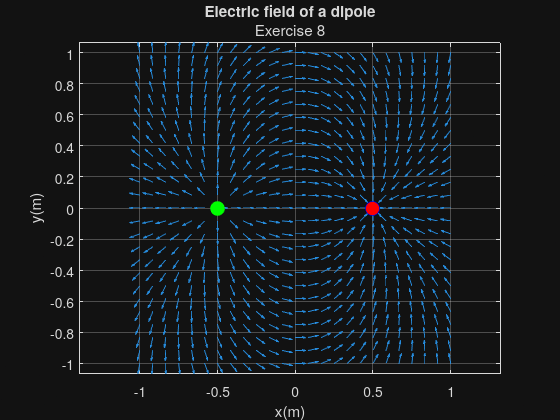

%constants
k = 9e9;
q_pos = 1e-9;
q_neg = -1e-9;

%define the grid
x = linspace(-1,1,25); % Slightly denser grid for better visualization
y = linspace(-1,1,25);
[X,Y] = meshgrid(x,y);

%positions of the charges
x_pos = -0.5; y_pos = 0;
x_neg = 0.5;  y_neg = 0;

%define the distance from positive charge
R_pos = sqrt((X - x_pos).^2 + (Y - y_pos).^2);
R_pos(R_pos==0) = eps; %avoid division by zero

%define the distance from negative charge
R_neg = sqrt((X - x_neg).^2 + (Y - y_neg).^2);
R_neg(R_neg==0) = eps;

%electric field from positive charge
E_mag_pos = k * q_pos ./ R_pos.^2;
Ex_pos = E_mag_pos .* ((X - x_pos)./R_pos);
Ey_pos = E_mag_pos .* ((Y - y_pos)./R_pos);

%electric field from negative charge
E_mag_neg = k * q_neg ./ R_neg.^2;
Ex_neg = E_mag_neg .* ((X - x_neg)./R_neg);
Ey_neg = E_mag_neg .* ((Y - y_neg)./R_neg);

%superposition (Total Electric Field)
Ex_total = Ex_pos + Ex_neg;
Ey_total = Ey_pos + Ey_neg;

%normalize total vectors
E_total_mag = sqrt(Ex_total.^2 + Ey_total.^2);
Ex_Norm = Ex_total ./ E_total_mag;
Ey_Norm = Ey_total ./ E_total_mag;

%plotting
figure;
quiver(X, Y, Ex_Norm, Ey_Norm, 0.6);
hold on;

%draw the point charges
plot(x_pos, y_pos, 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g'); % Positive
plot(x_neg, y_neg, 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'r'); % Negative

%formatting
axis equal;
xlabel("x(m)");
ylabel("y(m)");
title("Electric field of a dipole");
subtitle("Exercise 8");
grid on;
hold off;